%clear all
load ARTEMIS.mat;

prob=optimproblem; %initializzi il problema
start=100;%Definisci l'istante iniziale
N=10; %Time horizon

%Estrai i sottovettori
speed=ARTEMIS(1,start-1:start+N-1);
acceleration=ARTEMIS(2,start-1:start+N-1);
gear=ARTEMIS(3,start-1:start+N-1);
StateUpdate=@(input,cur_SOC,i)hev_MPC(speed(i),acceleration(i),gear(i),cur_SOC,input);

%Definisci l'handle della funzione di update dello stato
FullStateUpdate=@(u)full_horizon(u,N,0.55,StateUpdate);

u=optimvar('u',N,"LowerBound",-1.00000,"UpperBound",1.00000);

[compute_mf,feas]=fcn2optimexpr(FullStateUpdate,u,0.55);

Error using optim.problemdef.fcn2optimexpr
Incorrect number of input arguments to supplied function. Expected 1 but given 2.

Error in optim.problemdef.fcn2optimexpr

Error in fcn2optimexpr


feas_costr=sum(feas)==0;
prob.Constraints.feas=feas_costr;

prob.Objective=sum(compute_mf);
initialGuess.u=0.5*ones(N,1);

tic
[sol,cost,out1,out2,out3]=solve(prob,initialGuess, ...
    options=optimoptions('fmincon','Display','iter','StepTolerance',1e-3));

Solving problem using fmincon.
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0      11    7.408561e-03    0.000e+00    4.504e-04
    1      22    7.404047e-03    0.000e+00    4.521e-04    4.160e-03
    2      33    7.376380e-03    0.000e+00    4.629e-04    2.584e-02
    3      44    7.256503e-03    0.000e+00    4.948e-04    1.153e-01
    4      55    6.887440e-03    0.000e+00    4.220e-04    3.962e-01
    5      66    6.283344e-03    0.000e+00    4.660e-04    7.511e-01
    6      77    6.209089e-03    0.000e+00    5.020e-04    4.200e-01
    7      88    6.128982e-03    0.000e+00    4.266e-04    1.704e-01
    8     101    6.128823e-03    0.000e+00    3.056e-04    8.835e-03
    9     112    6.128127e-03    0.000e+00    4.252e-04    6.873e-03
   10     123    6.127471e-03    0.000e+00    4.252e-04    9.367e-04

L

toc

Elapsed time is 1.449459 seconds.


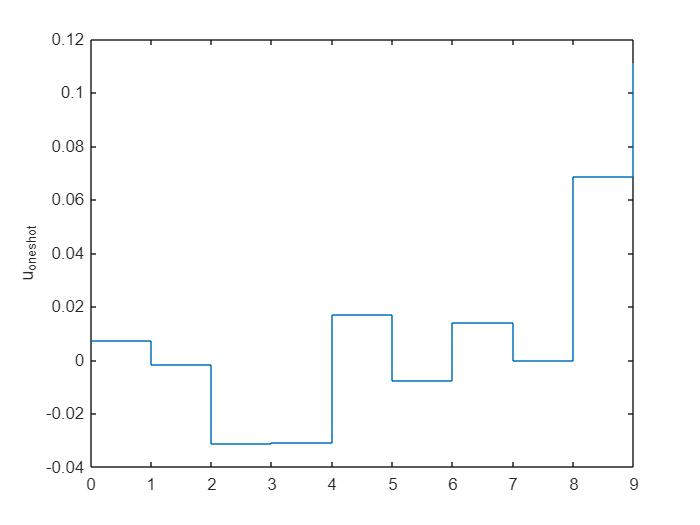

u_oneshot=sol.u;
stairs(0:1:N-1,u_oneshot)
ylabel('u_oneshot')

% [mf_eq,I,SOC]=FullStateUpdate(sol.u,0.55);
% plot(SOC)
% stairs(speed*3.6)
% ylabel('acceleration')

N_it=10;
u_fin=zeros(N_it,1);
for j=1:N_it
    %Estrai i sottovettori
    speed=ARTEMIS(1,(1+j+start):(N+j+start));
    acceleration=ARTEMIS(2,1+N*j+start:N+N*j+start);
    gear=ARTEMIS(3,1+N*j+start:N+N*j+start);
    StateUpdate=@(input,cur_SOC,i)hev_MPC(speed(i),acceleration(i),gear(i),cur_SOC,input);
    FullStateUpdate=@(u,SOC_0)full_horizon(u,N,SOC_0,StateUpdate);
    [compute_mf,feas]=fcn2optimexpr(FullStateUpdate,u,0.55);
    prob.Objective=sum(compute_mf);
    initialGuess.u=[sol.u(2:end);0.5];
    sol=solve(prob,initialGuess,options=optimoptions('fmincon'));
    u_fin(j)=sol.u(1);
end

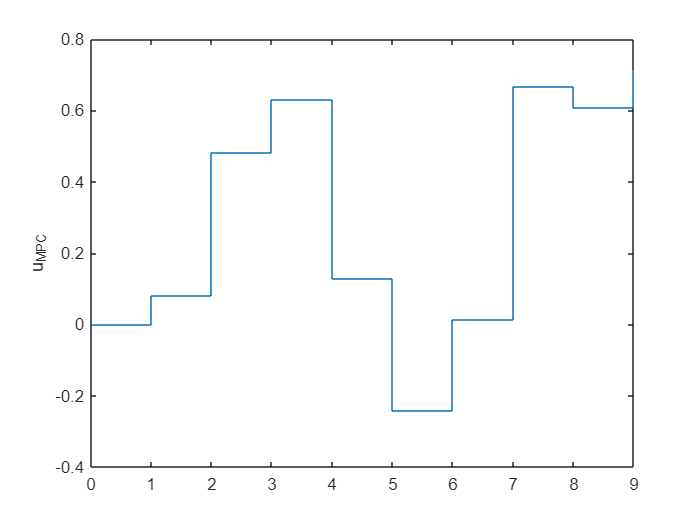

stairs(0:1:N_it-1,u_fin)
ylabel('u_MPC')

sum(FullStateUpdate(u_oneshot,0.55))-sum(FullStateUpdate(u_fin,0.55))

ans = -8.0001